stili linee

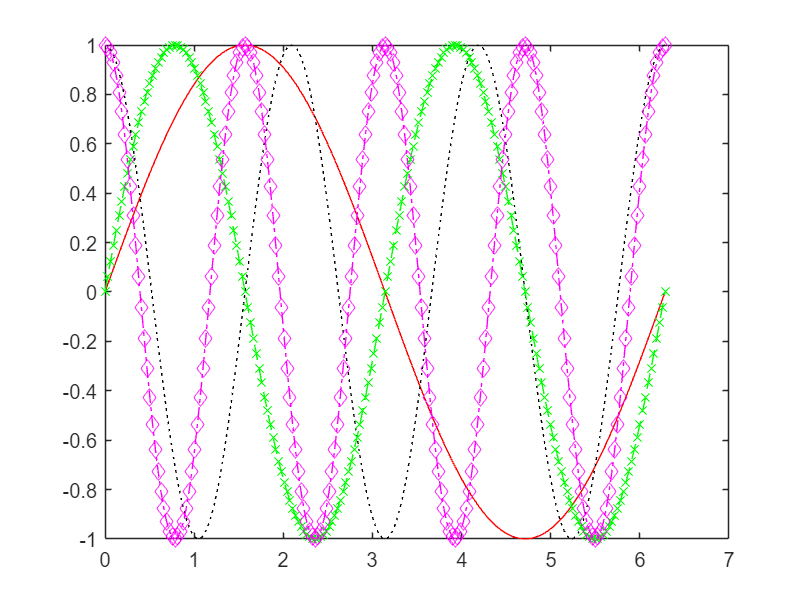

x=0:pi/100:2*pi;
y1=sin(x);
y2=cos(3*x);
y3=sin(2*x);
y4=cos(4*x);
plot(x,y1,'r')
hold on
plot(x,y2,':k')
plot(x,y3,'--xg')
plot(x,y4,'-.dm')
close all
plot(x,y1,'r', x,y2,':k',x,y3,'--xg', x,y4,'-.dm')

limiti degli assi

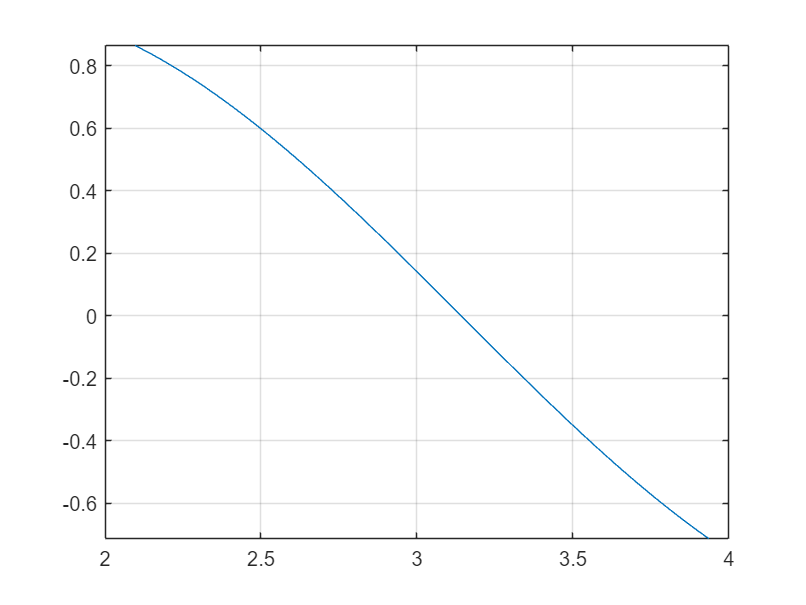

x=0:pi/100:2*pi;
y=sin(x);
plot(x,y)
xlim([2 4])
ylim([-0.5 0.5])
grid
axis equal

legende e annotazioni

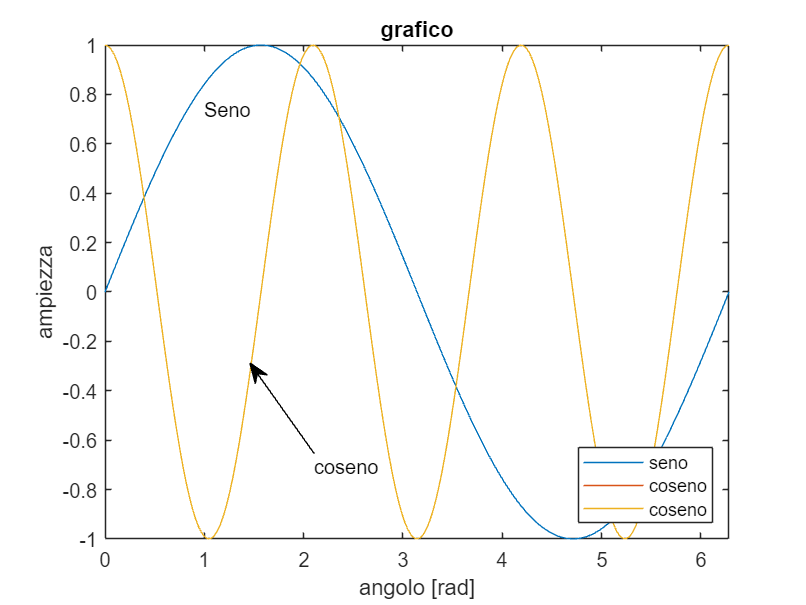

x=0:pi/100:2*pi;
y1=sin(x);
y2=cos(3*x);
plot(x,y1,'displayname','seno')
hold on
plot(x,y2,'displayname','coseno')
plot(x,y2,'displayname','coseno')
axis([0 2*pi -1 1])
title('grafico')
xlabel('angolo [rad]')
ylabel('ampiezza')
legend('show','location','southeast')
text(1,sin(1)-0.1,'Seno')
annotation('textarrow',[0.39 0.31], [0.25 0.4], 'String', 'coseno')

grafici con due assi

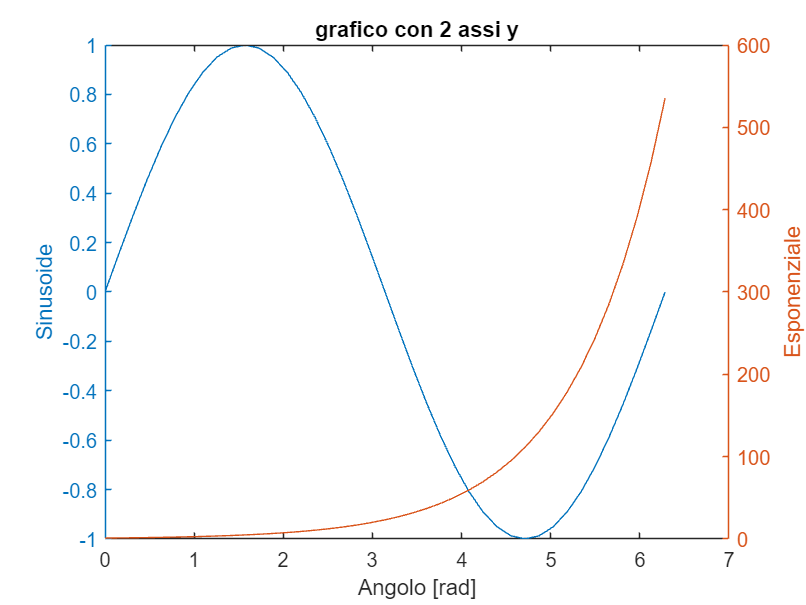

x=0:pi/20:2*pi;
y1=sin(x);
y2=exp(x);
figure
title('grafico con 2 assi y')
xlabel('Angolo [rad]')
yyaxis left
plot(x,y1)
ylabel('Sinusoide')
yyaxis right
plot(x,y2)
ylabel('Esponenziale')

grafici logaritmici

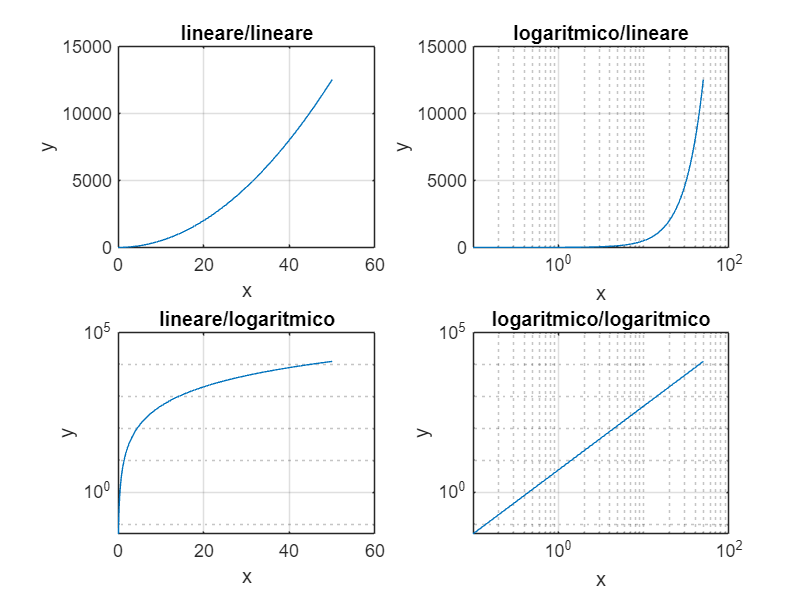

x=0:0.1:50;
y=5*x.^2;
subplot(221)
plot(x,y)
grid
title('lineare/lineare')
xlabel('x')
ylabel('y')
subplot(222)
semilogx(x,y)
grid
title('logaritmico/lineare')
xlabel('x')
ylabel('y')
subplot(223)
semilogy(x,y)
grid
title('lineare/logaritmico')
xlabel('x')
ylabel('y')
subplot(224)
loglog(x,y)
grid
title('logaritmico/logaritmico')
xlabel('x')
ylabel('y')

grafici discreti

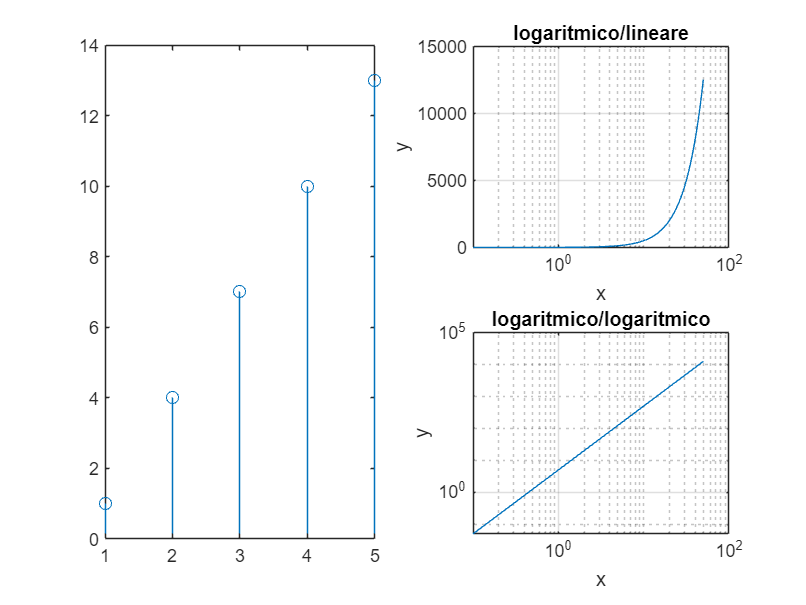

x=1:5;
y=3*x-2;
subplot(121)
stem(x,y)

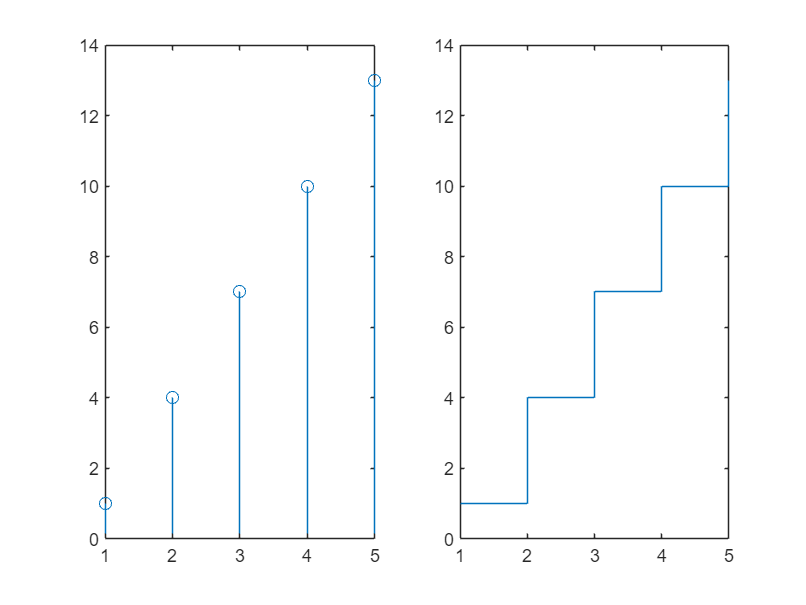

subplot(122)
stairs(x,y)

grafici a barre

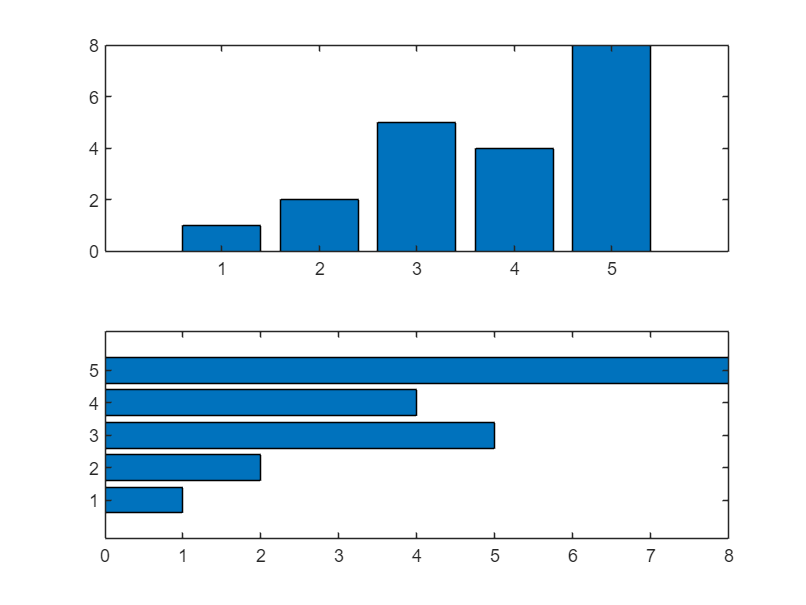

x=[1 2 5 4 8];
subplot(211)
bar(x)
subplot(212)
barh(x)

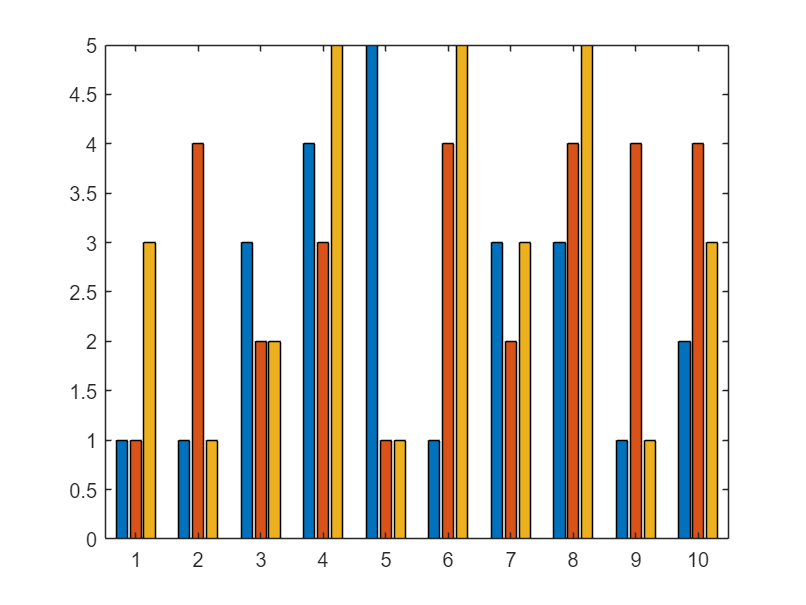

figure
bar(randi(5,10,3))

grafici a torta

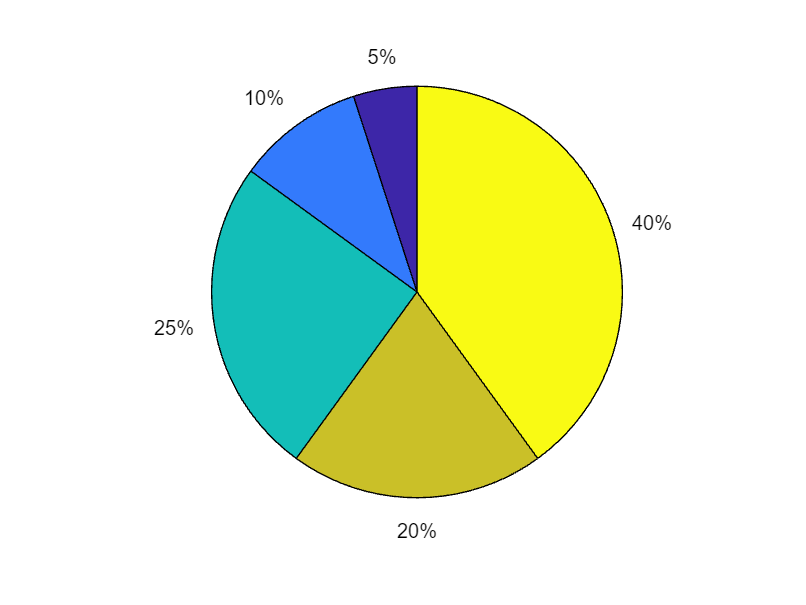

x=[1 2 5 4 8];
pie(x)

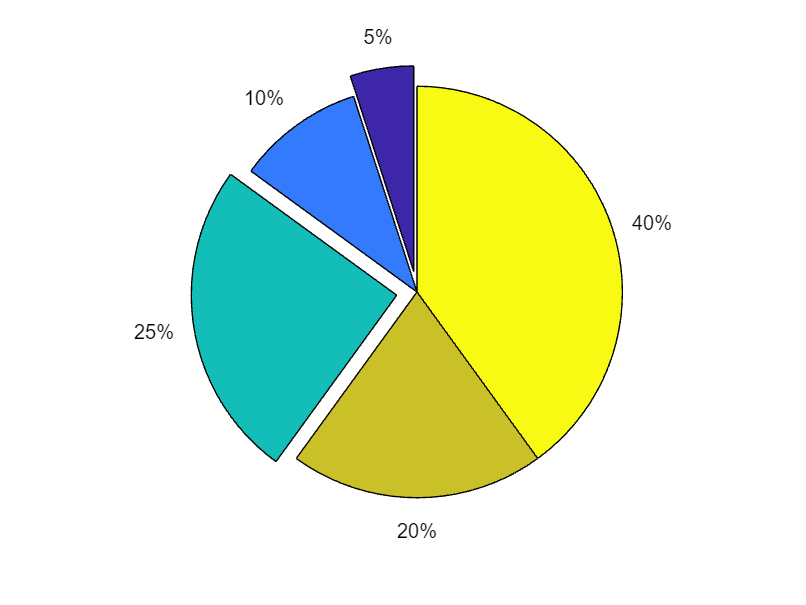

figure
pie(x, [1 0 1 0 0])

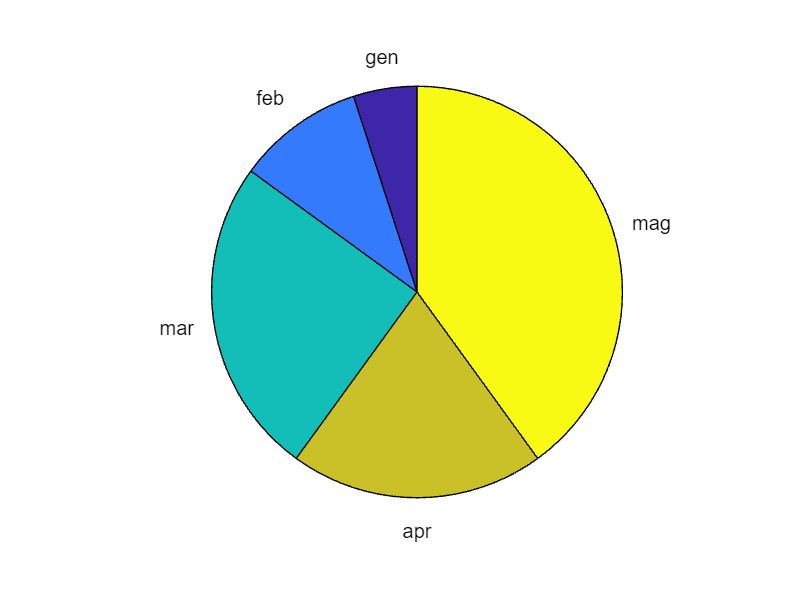

pie(x, ["gen" "feb" "mar" "apr" "mag"])

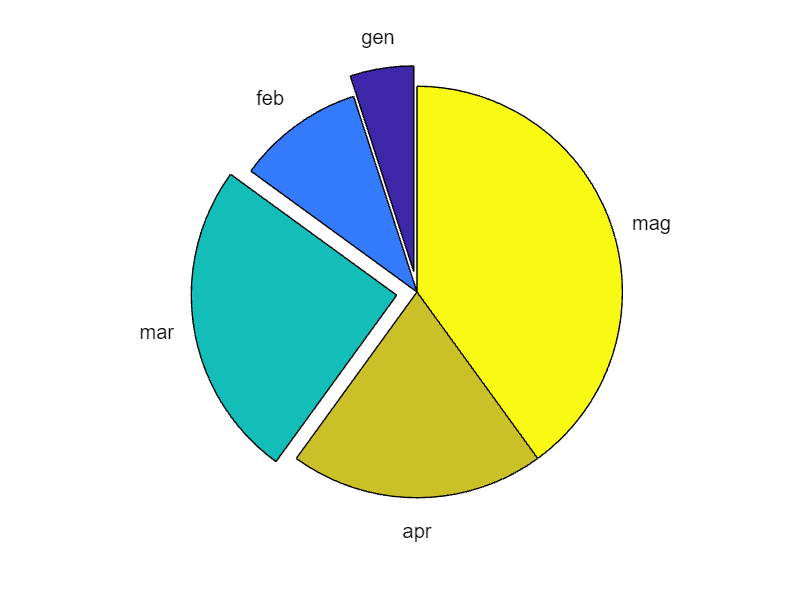

pie(x, [1 0 1 0 0], ["gen" "feb" "mar" "apr" "mag"])

Grafici tridimensionali a linee

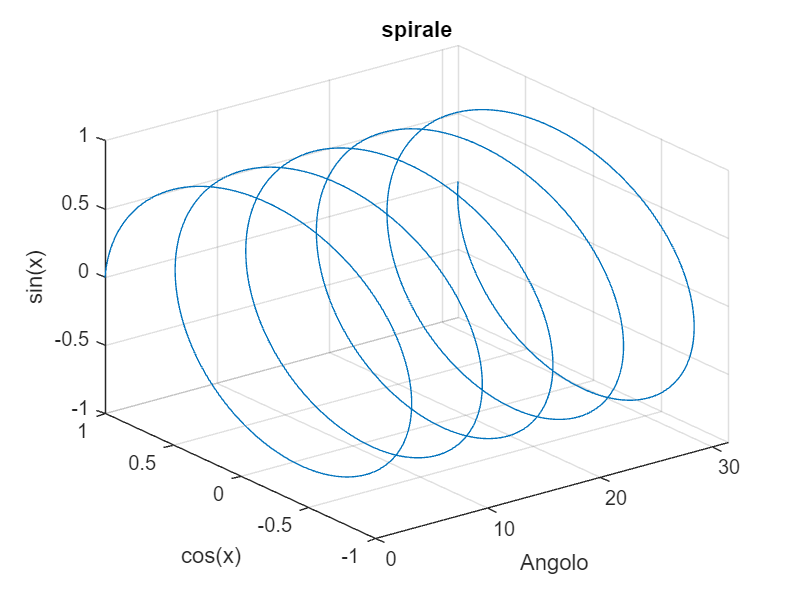

x=linspace(0,10*pi,1000);
y=cos(x);
z=sin(x);
plot3(x,y,z)
grid
title('spirale')
xlabel('Angolo')
ylabel('cos(x)')
zlabel('sin(x)')

Grafici di superifici

% x=linspace(1,50,10);
% y=linspace(500,1000,3);
% z=[1:10;2:2:20;3:12];
% subplot(121)
% mesh(x,y,z)
% xlabel('x')
% ylabel('y')
% zlabel('z')
% subplot(122)
% surf(x,y,z)
% xlabel('x')
% ylabel('y')
% zlabel('z')
% shading interp
% colormap abyss

grafici di funzioni a due variabili

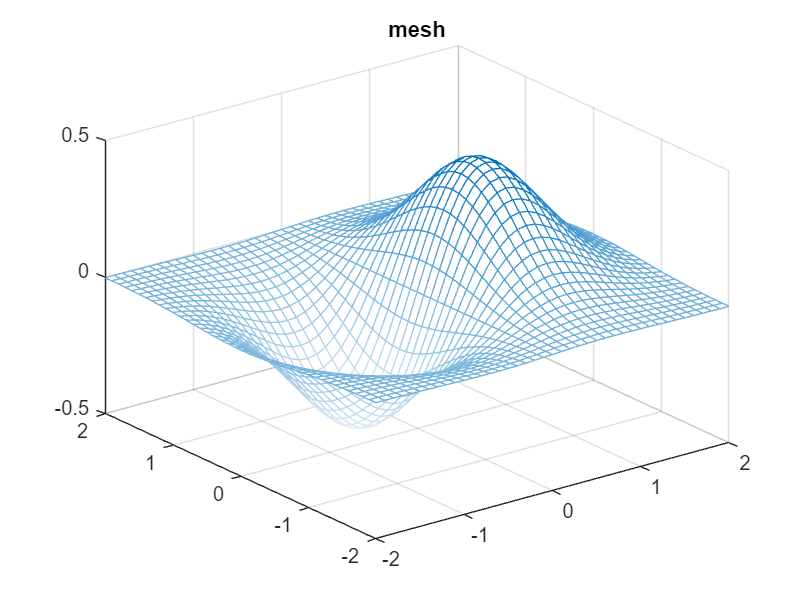

x = -2:0.1:2;
y = -2:0.1:2;
[X,Y] = meshgrid(x);
Z = X.*exp(-X.^2 - Y.^2);
mesh(X,Y,Z)
colormap sky
title('mesh')

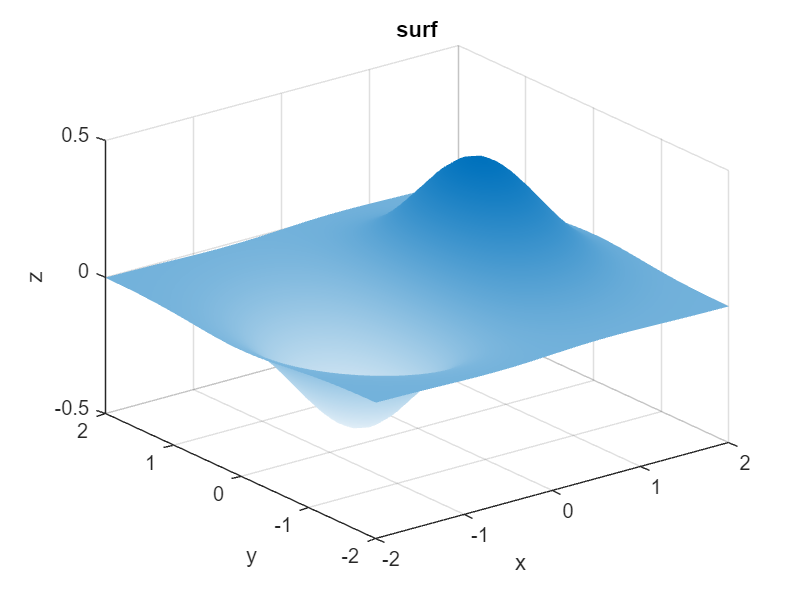

figure
surf(X,Y,Z)
shading interp
colormap sky
title('surf')
xlabel('x')
ylabel('y')
zlabel('z')